## vna_reader_2.mlx

This is the corrected version of obtaining the impulse response from S21 VNA parameter data. Using MATLAB's SerDes library, the problem boils down to an already solved communication channel characterization problem.

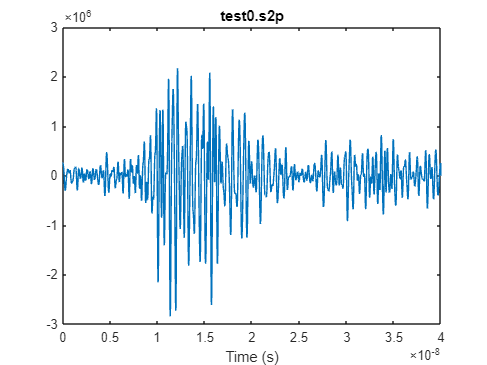

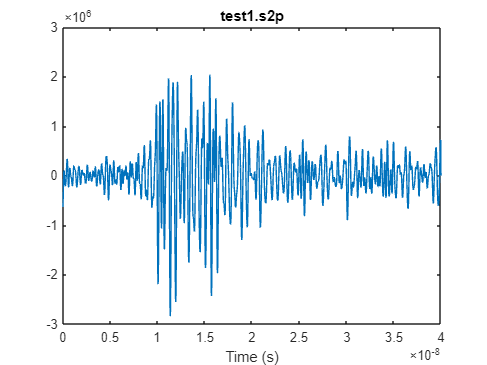

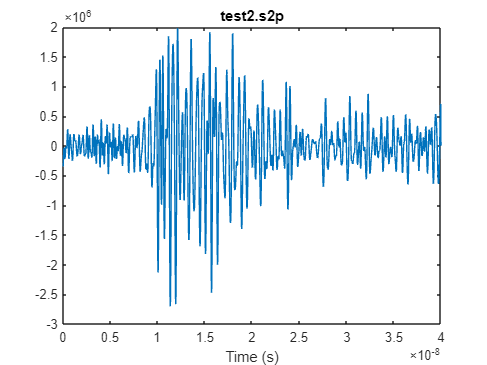

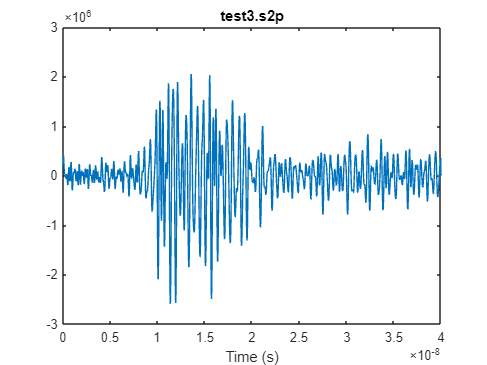

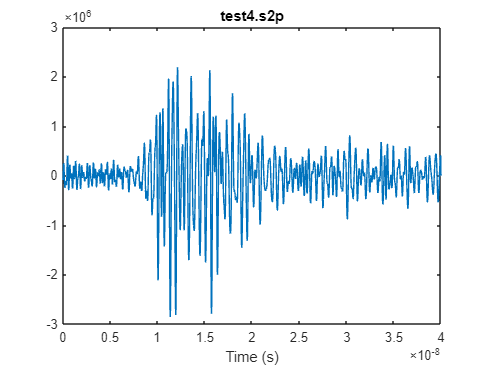

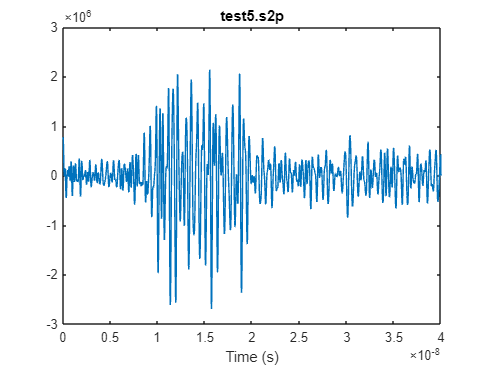

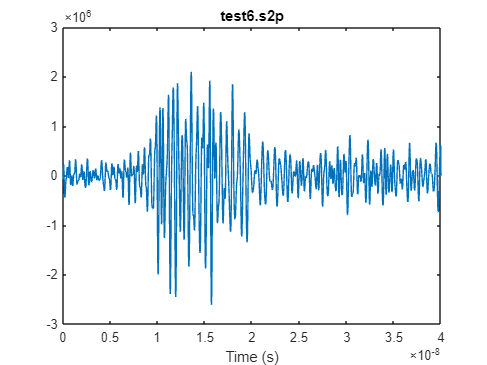

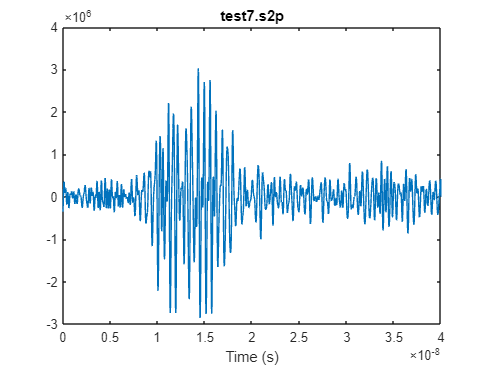

close all; clear;

% look for all the files named "testX.s2p"
% and open them as s-parameter objects in a list
fileprefix = "test";
directory = pwd;

% Get a list of all files in the directory
files = dir(fullfile(directory, [fileprefix + '*.s2p']));
% Determine the number of files found
num_files = numel(files);

% Initialize a cell array to store the data from each file
sparamCell = cell(1, num_files);
figure;
for i = 1:num_files
    % Construct the filename
    obj = SParameterChannel('FileName',files(i).name,...
    'PortOrder', [2 1],...
    'MaxNumberOfPoles', 84,...
    'ErrorTolerance', -40,...
    'SampleInterval', 6.25e-12,...
    'StopTime', 40e-9,...
    'TxR',50,...
    'TxC',0.1e-12,...
    'TxAmplitude', 1.0,...
    'TxRiseTime', 1e-11,...
    'TxRTFactor', 0.6,...
    'RxR',50,...
    'RxC',0.2e-12,...
    'Signaling','single-ended',...
    'AggressorDefinition','same-load');
    tf = obj.TransferFunction;
    
    %[mag, phase, wout] = bode(tf);
    %figure(wout, phase);
    t = obj.t;
    impulse = obj.ImpulseResponse;
    figure;
    plot(t,impulse);
    title(files(i).name)
    xlabel("Time (s)")
end

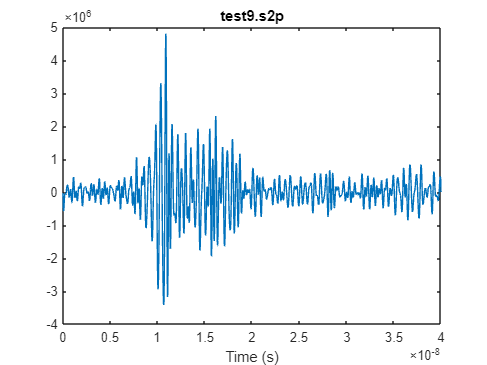

hold off;